# Multivariate scattered interpolation

## Halton dataset

d = 2;                                              % d = space dimension
N = (2^4+1)^2;                                      % N = number of scattered points in R^d

% Generate quasi - random Halton set (see MATLAB Doc for Skip and Leap properties )
p = haltonset (d,'Skip' ,1e3 ,'Leap' ,1e2 );        % define quasi - random object in d- dim
p = p.scramble ('RR2');                             % use scramble method ( reverse - radix )
X = p.net (N);                                      % use net method to generate N points in R^d
F = franke(X);                                      % compute Franke 's test function


## RBF interpolator

dist_name = 'Euclidean';                         % define a distance
phi = @(r) r .^3;                                % define an RBF
D = pdist(X, dist_name );                        % 1) compute pairwise distances
A = squareform (phi(D));                         % 2) apply RBF to distances
lambda = A\F;                                    % 3) solve linear system A* lambda = F

## Cubic RBF interpolator with Linear Tail

P = [ones(N,1), X];                           % define P =[1 xi yi ] as N x 3
A0 = [A P; P' zeros(3)];                      % define augmented interpolation matrix
F0 = [F; zeros(3,1)];                         % add zeros to F
lambda0 = A0\F0                               % solve linear system A0* lambda0 = F0

lambda0 =    -1.7105
   -0.6756
   -7.0598
    2.9444
  -20.5584
   -0.9048
  -10.3760
   -3.0182
   -2.0062
   -3.2715


## Play

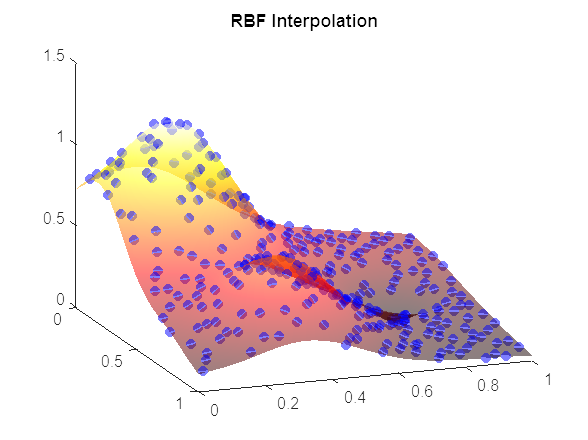


N = 289; 
range = [0 1 0 1]; 
sequenceType = "halton";
RBF = "Cubic";
fi = "franke";

% Cubic RBF interpolator 
Xnew = points_qrgenerator(2,N, sequenceType, range);
[lambda, error, A] =rbf_interp(Xnew,fi,RBF,range,30);

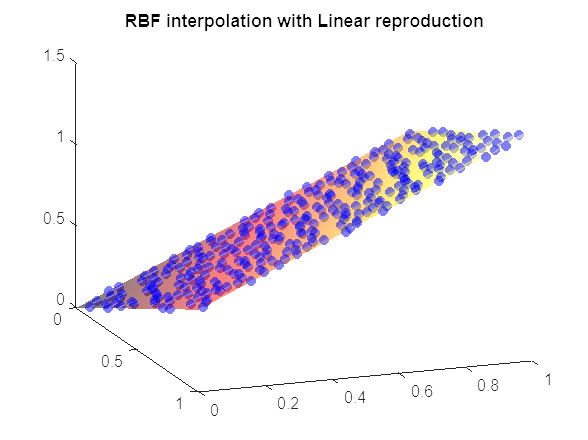


% Cubic RBF interpolator with Linear Tail "pol1"
fi_test = @(x) 0.5*x(:,1) + 0.9*x(:,2); 
[lambda0, error1, A1] =rbf_interp(Xnew ,fi_test,RBF,range,30, [], "pol1");

function values = franke(x)
%FRANKE Franke's bivariate test function.

values = .75*exp(-((9*x(:,1)-2).^2 + (9*x(:,2)-2).^2)/4) + ...
    .75*exp(-((9*x(:,1)+1).^2)/49 - (9*x(:,2)+1)/10) + ...
    .5*exp(-((9*x(:,1)-7).^2 + (9*x(:,2)-3).^2)/4) - ...
    .2*exp(-(9*x(:,1)-4).^2 - (9*x(:,2)-7).^2);
end

function values = rastrigin(x)
%RASTRIGINSFCN Compute the "Rastrigin" function.
d = size(x,2);
A = 10;
values = A*d + sum(x .^2 - A* cos(2*pi .*x),2);
end  

function values  = ackley(x)
%ACKLEYFCN Compute the Ackley function.
% 
% scores = zeros(size(x,1),1);
% for i = 1:size(x,1)
%     p = x(i,:);
%     % on the interval [-32.768 32.768]
%     p = max(-32.768,min(32.768,p));
%     
%     scores(i) = 20 + exp(1) - 20 * exp( -0.2 * exp ( sqrt( (1/length(p)) * sum(p .^ 2)) - exp((1/length(p)) * sum(cos(2*pi .* p)))));
% end

d = size(x,2);
values  = 20 + exp(1) - 20*exp(-0.2*exp(sqrt((1/d)*sum(x.^2,2))-exp((1/d)*sum(cos(2*pi.*x),2))));
end

function phi = thinplatesplineRBS(r, gamma)
if nargin == 1, gamma = 1; end
phi = zeros(size(r));
idx = r ~=0;
phi(idx) = (gamma*r(idx)).^2.*log(gamma*r(idx));
end
function points = points_qrgenerator(d,N, type, range)
% Type can be either Halton or Sobol
switch type
    case "halton"
        p = haltonset(d,'Skip',1e3,'Leap',1e2); % skip the first 1000 values, then retain every 101st point.
        p= scramble(p,'RR2');   %Apply reverse-radix scrambling
     
    case "sobol"
        p = sobolset(d,'Skip',1e3,'Leap',1e2);
        p = scramble(p,'MatousekAffineOwen');
        
end
   a = range(1); b = range(2);
   c = range(3); d = range(4);
   points = net(p, N).*[b-a, d-c] + [a c];
   

end

function [coeff, maxerror, A] = rbf_interp(points,fi_,RBF,range,n, fi_exact, pol1)
% if fi contains 

Dist_ij = squareform(pdist(points, "euclidean"));
switch RBF
    case "Linear"
        phi = @(r) r; % linear RBF 
    case "Cubic"
        phi = @(r) r.^3; % cubic RBF
    case "Thin-plate spline"
        phi = @(r) thinplatesplineRBS(r); % RBF
    case 'Gaussian'
        ep = 0.2;
        phi = @(r) exp(-ep*r.^2); % RBF
end

A = phi(Dist_ij); % RBF applied to Distance matrix

if ~isnumeric(fi_)
    if isstring(fi_)
        switch fi_
            case "franke"
                fi = franke(points);
            case "rastrigin"
                fi = rastrigin(points);
            case "ackley"
                fi = ackley(points);
        end
    elseif isa(fi_, "function_handle")
                fi = fi_(points);
    end
else
    fi = fi_;
end

figure, hold on
scatter3(points(:,1),points(:,2),fi, "b", "filled")

%%%%%%%%% Only for linear 2D reproduction *******
if nargin == 7
    if size(points,2) ~= 2, error("Linear reproduction is only for 2D."), end
    fi = [fi; zeros(3,1)]; % add zeros for linear reproducion in 2-dim
    P = [ones(size(points,1),1), points];  % [1 xi yi ] is N x 3
    A = [A P; P' zeros(3)];  % augmented interpolation matrix
end
%%%%%%%%% END - Only for linear 2D reproduction *******

% solution of linear system
coeff = A\fi;

if nargin <=3 || isempty(range)
    range = [0 1 0 1];
end

if nargin <= 4
    nx = 30;
    ny = 30;
end
if nargin >= 5
    if numel(n) == 1
        nx = n;
        ny = n;
    elseif numel(n) == 2
        nx = n(1);
        ny = n(2);
    else
        error("n is not specified correctly.")
    end
end

% Uniform Grid for evaluation
gridx = linspace(range(1),range(2), nx);
gridy = linspace(range(3),range(4), ny);
[xe,ye] = meshgrid(gridx, gridy);
epoints = [xe(:), ye(:)];

eDist = pdist2(epoints,points);
eA = phi(eDist);

%%%%%%%%% Only for linear 2D reproduction *******
if nargin == 7
     eP = [ones(nx*ny,1) epoints];
     eA = [eA, eP];
end
%%%%%%%

f_interp = eA * coeff;
f_interp_mat = reshape(f_interp,nx,ny);

surf(xe,ye,f_interp_mat )
view([70 20])
shading interp
alpha(0.5)
colormap hot

% Error 
msg = "";
maxerror = "";
if isstring(fi_) || isa(fi_, "function_handle")
        if nargin < 7
        intro = "RBF Interpolation";
        else
            intro = "RBF interpolation with Linear reproduction";
        end
        msg = " -->  Max Error:  ";
        if isstring(fi_)
        switch fi_
            case "franke"
                fi_exact = franke(epoints);
            case "rastrigin"
                fi_exact = rastrigin(epoints);
            case "ackley"
                fi_exact = ackley(epoints);
        end
        else % fi_ is handle
            fi_exact = fi_(epoints);
        end
        maxerror = norm(fi_exact-f_interp);
elseif nargin == 6 & isnumeric(fi_exact) & numel(fi_exact) == numel(f_interp)
    maxerror = norm(fi_exact-f_interp);
   
end


title({intro; ...
       "RBF: " + RBF + msg  + maxerror})


title(intro)
end









